# System parameter calculations

The goal of this script is to compute the dimensions of the various diemnsions of the parts of the 2 stage zero stiffness variable position and mass gravity compensation. It does so using the given constraints, prefrences and part selection 

clear all; close all
addpath("Spring calcuations") %adding path for spring calculations
Trekveren = readtable('Trekveren.xlsx');

#### Material constants

g = 9.81;
%alluminium
E_allu = 69E9; %   
sigma_y_allu = 124E6; %steel https://www.steelinox.nl/nl/informatie/roestvast-staal-info
%https://www.gamma.nl/assortiment/plat-profiel-rvs-15x0-5x1000mm/p/B175454
E_steel = 190E9; %[Pa] elastic modulus of steel 
sigma_y_steel = 250E6; %[Pa] yield stress steel
%pvc -> https://www.naeff.nl/nl/technische-datasheet/polyvinylchloride-pvc-u?n=2690_3
%https://www.praxis.nl/gereedschap-installatiemateriaal/ijzerwaren/profielen-platen/profielen/alberts-platte-stang-kunststof-wit-25x2mm-1m/5535075
E_pvc = 3000E6; %[Pa]
sigm_y_pvc = 58E6; %[Pa] %flow tension is used, as this is an underirable effect

#### System constants

m2 = .8;                 %[kg] unloaded mass
m1 =2;                 %[kg] loaded mass
m_s2 =1;               %[kg] second stage mass
sys_angle =28/180*pi;  %[rad] angle at which the mirror is located 
t = 0.006;               %[m] thickness of plate material that will be used for construction

#### Constraints

h_max = .4;             %[m] maximal height mass compensator      
sf = 1.1; %safety margin 10%
%{
d_mirror = .16;
Longstroke = d_mirror*sin(sys_angle)*3 %[m] stroke of the first stage
S1 = Longstroke*sf 
%}
S1 = 160E-3; %[m] long stroke mechanism
S2 = 5e-3; %[m] short stroke mechanism

### parameters

R1 = 15E-3;             %[m] inner radius -> constraint by material design of the pulley system
F1 = m1*g + m_s2*g;     %[N] initial load on the system
F2 = m2*g + m_s2*g;     %[N] second loading condition
h_mech = 5*t;           %[m] 5 plate material of space needed for construction
SR = 1/3;               %[] spring elongation ratio used to estimate spring properties

### Desired properties

stage1 = springsystem(F1,F2,S1,h_mech,h_max,SR, 10E-3); %defining the spring system
stage1 = stage1.comp_sys(2) %computing the system properties

stage1 =   springsystem with properties:

              F1: 29.4300
              F2: 17.6580
              L0: 0.1024
              L1: 0.0448
              L2: 0.0269
            Lmax: 0.3072
               S: 0.1600
    springstroke: []
      max_stroke: 0
              R1: 0.0100
              R2: 0.0448
          h_mech: 0.0300
        h_adjust: 0.0179
           h_max: 0.4000
               k: 656.4700
              SR: 0.3333
          Fn_tot: []
            name: []
               n: []


stage1.desired_properties()

    "k = 656.47"

    "l0 = 102.4123"

    "fn = 204.8307"

    "Fn = 134.4652"



### Spring selection

Bellow various springs parameters are inserted and the function keeps the best spring parameters.

stage1springs = table(); %clearing the table value 
for i = 1 : height(Trekveren)
    spring = Trekveren(i,:);
    for j = 1 :2 %Iterating over amount of springs
        springs_sys = stage1.real_spring_properties(spring.Lo, spring.fn, spring.Fn, j); %computing the new spring system with given spring
        spring.('n') = j;                                               %[] number of springs
        spring.('stroke') = springs_sys.max_stroke *1e3;                %[mm] possible stroke of the system
        spring.('S/price') = spring.n * spring.stroke/spring.prijs;     %[mm/€] price per mm stroke
        spring.('enough_stroke') = spring.stroke >= S1*1e3;             %[] determening if desired stroke is reached
        spring.('k') = springs_sys.k;                                   %[n/m] stiffness
        stage1springs = [stage1springs ; spring]; %adding spring to result table
    end
end
stage1springs = sortrows(stage1springs,'k','ascend'); %sorting for lowest stiffness
stage1springs = sortrows(stage1springs,'enough_stroke','descend') %sorting for if desired stroke has been reached

stage1springs = 868×14 table
    Artikelcode     d       Dm      Lo       fn        Fn       R        Materiaal       prijs    n    stroke    S/price    enough_stroke     k  
    ___________    ____    ____    _____    _____    ______    ____    ______________    _____    _    ______    _______    _____________    ____

    {'TR3450'}     3.75    39.2    154.2    211.3       277    1.11    {'RVS 302'   }    12.48    1    161.92    12.975         true         1311
    {'T1820' }      2.2    21.8      122      188       

selected_spring = stage1springs(1,:); %selecting the best spring from the table above
stage1.name = selected_spring.Artikelcode;
stage1.n = selected_spring.n;
stage1 = stage1.real_spring_properties(selected_spring.Lo, selected_spring.fn, selected_spring.Fn, selected_spring.n) %inserting our final spring properties 

stage1 =   springsystem with properties:

              F1: 29.4300
              F2: 17.6580
              L0: 0.1542
              L1: 0.0224
              L2: 0.0135
            Lmax: 0.3386
               S: 0.1619
    springstroke: 0.1889
      max_stroke: 0.1619
              R1: 0.0100
              R2: 0.0224
          h_mech: 0.0300
        h_adjust: 0.0090
           h_max: 0.4000
               k: 1311
              SR: 0.3333
          Fn_tot: 277
            name: {'TR3450'}
               n: 1


### Pulley design

Here the dimensions of our desired pulley is computed and exported to pulley.xlsx.

The second loading curve is drawn to show the missmatch in curve in the second loading condition

figure()
clf
hold on
r1 = stage1.R1;
r2 = stage1.R2;

k = stage1.k;
n_steps = 800;
for i = 1:2
    if i == 1 %selecting the loading condition 
        F0 = stage1.F2;
    else
        F0 = stage1.F1;
    end
    S = F0*r2/k;
    T = F0*r2/(k*r1);
    stepsize = (r2- r1)/n_steps;
    r = [r1:stepsize:r2];
    theta = -sqrt(S^2- r.^4)./(2*r.^2) + 0.5 *asin(r.^2/S) ;
    const = theta(1);
    theta = theta - const; %adding constant such that theta(1) = 0
    x = real(cos(theta).*r*1e3);
    y = real(sin(theta).*r*1e3);
    plot(x,y)
end

F0 = 29.4300

F0 = 17.6580

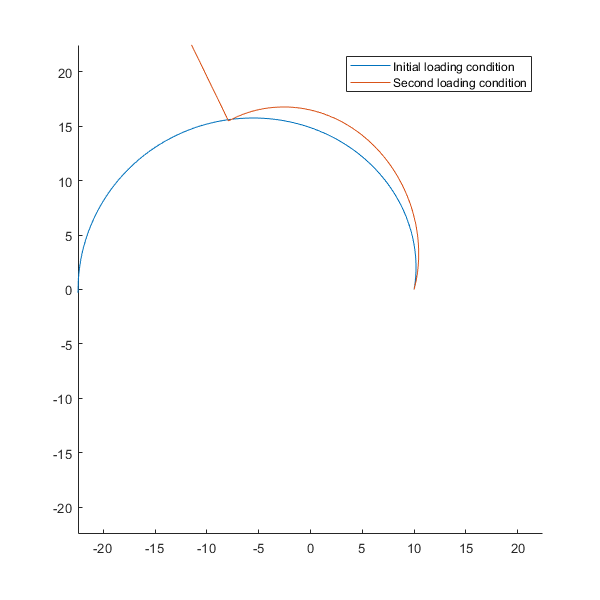

output = table(transpose(x),transpose(y)); %saving data to excel sheet to draw in CAD
writetable(output,'pulley.xlsx');
    
legend('Second loading condition','Initial loading condition')
set(gcf, 'Position',  [100, 100, 600, 600])

xlim([-r2,r2]*1e3)
ylim([-r2,r2]*1e3)

# Second stage 

The second stage consist out of two parts, the negative spring system and the positive spring system

### parameters

F1 = m1*g;      %[N] initial load on the system
F2 = m2*g;      %[N] second loading condition
reduction = 0.9; %[]desired stiffness reduction
n =4;          %[]number of leaf springs
SR = 1/2;       %[]spring ratio is lower with smaller sizes
h_mech = 5*t;   %[]height positive spring construction
h_max = round(stage1.h_max - 2*stage1.R2 - stage1.S, 2);%second stage maximal height
h2n = S2 * 8;           %[m] max heigh negative spring
h2p = h_max - h2n;      %[m] max height positive spring
h_max, h2n, h2p %printing out the resulting dimensions

h_max = 0.1900

h2n = 0.0400

h2p = 0.1500

### Desired positive spring

stage2p = springsystem(F1,F2,S2,h_mech,h2p,SR,0); %creating the secondstage positive spring system
stage2p = stage2p.comp_sys(2) %computing the system parameters 

stage2p =   springsystem with properties:

              F1: 19.6200
              F2: 7.8480
              L0: 0.0579
              L1: 0.0529
              L2: 0.0212
            Lmax: 0.1158
               S: 0.0050
    springstroke: []
      max_stroke: 0
              R1: 0
              R2: 0
          h_mech: 0.0025
        h_adjust: 0.0317
           h_max: 0.1500
               k: 371
              SR: 0.5000
          Fn_tot: []
            name: []
               n: []


stage2p.desired_properties() %showing desired spring properties

    "k = 371"

    "l0 = 57.8848"

    "fn = 57.8841"

    "Fn = 21.475"



### Second stage positive spring selection

stage2psprings = table(); %clearing the table value 
for i = 1 : height(Trekveren)
    spring = Trekveren(i,:);
    for j = 1 :2 %Iterating over amount of springs
        springs_sys = stage2p.real_spring_properties(spring.Lo, spring.fn, spring.Fn, j); %computing the new spring system with given spring
        spring.('n') = j;                                               %[] number of springs
        spring.('stroke') = springs_sys.max_stroke *1e3;                %[mm] possible stroke of the system
        spring.('S/price') = spring.n * spring.stroke/spring.prijs;     %[mm/€] price per mm stroke
        spring.('enough_stroke') = spring.stroke >= S2*1e3;             %[] determening if desired stroke is reached
        spring.('k') = springs_sys.k;                                   %[n/m] stiffness
        stage2psprings = [stage2psprings ; spring]; %adding spring to result table
    end
end
stage2psprings = sortrows(stage2psprings,'k','ascend'); %sorting for lowest stiffness
stage2psprings = sortrows(stage2psprings,'enough_stroke','descend') %sorting for if desired stroke has been reached

stage2psprings = 868×14 table
    Artikelcode     d       Dm      Lo      fn      Fn      R        Materiaal       prijs    n    stroke    S/price    enough_stroke     k 
    ___________    ____    ____    ____    ____    ____    ____    ______________    _____    _    ______    _______    _____________    ___

    {'T450'  }     0.63    6.37      35    66.5    12.2    0.16    {'Verenstaal'}    2.39     2     13.04    10.912         true         367
    {'TR700' }      0.8     8.2    44.6    85.6    15.8    0.16    {'R

selected_spring = stage2psprings(1,:); %selecting the best spring from the table above
stage2p.name = selected_spring.Artikelcode;
stage2p.n = selected_spring.n;
stage2p = stage2p.real_spring_properties(selected_spring.Lo, selected_spring.fn, selected_spring.Fn, selected_spring.n) %inserting our final spring properties 

stage2p =   springsystem with properties:

              F1: 19.6200
              F2: 7.8480
              L0: 0.0350
              L1: 0.0535
              L2: 0.0214
            Lmax: 0.1154
               S: 0.0270
    springstroke: 0.0130
      max_stroke: 0.0130
              R1: 0
              R2: 0
          h_mech: 0.0025
        h_adjust: 0.0321
           h_max: 0.1500
               k: 367
              SR: 0.5000
          Fn_tot: 24.4000
            name: {'T450'}
               n: 2


### Negative spring design

Below are the design parameters of the negative spring design

kn = round(stage2p.k*reduction) %desired negative spring stiffness

kn = 330

E = E_steel; %selecting material properties 
sigma_y = sigma_y_steel;
t = 0.5e-3; %[m] thickness plate steel
b = 15e-3; %[m] widht plate steel 

#### Viability short stroke 

Below are computation to estimate the viability of the system

I = t^3*b/12; %[m^4]  moment of inertia leaf spring
%L_desired = ( ( (S2)^2 * 53 * E *t)/(sigma_y*5/3) )^(1/3) %leaf spring length given the desired stroke 

L_desired = 0.0671

stage2n = negative_spring(E_steel,sigma_y,t,b,n,kn)

stage2n =   negative_spring with properties:

          E: 1.9000e+11
    sigma_y: 250000000
          t: 5.0000e-04
          b: 0.0150
          n: 4
         sm: 0.8700
          I: 1.5625e-13
          L: 0.2519
          k: 330
     uz_max: 0.0032
          S: 0.0316


resulting_stiffness = stage2p.k - stage2n.k

resulting_stiffness = 37

# Imperfection analysis

It is not possible to build to the micrometer perfectly, therefore we have to be sure that even given imperfect parts that are system is still **tunable **such that it is opertable and that given the build margin it is still stable.

margin =1.1;


## Connecting rods

The two stages are connected trough threaded rods, here the stiffness is compared to the stiffness of the negative spring

It has to be sufficiently stiff such that it does not influence the performance of the negative springs

d = 4

d = 4

r = d/2 * 1e-3;
L = 150e-3;
I = pi / 4 * r^4;
k = round(3*E_steel*I/L^3)*2

k = 4244


k/kn

ans = 12.8606